% #519
% Solve equation
% (1+exp(2*x))*y^2*dy=exp(x)*dx
% y(0)=0

syms x y dx dy real;
eq1=(1+exp(2*x))*y^2*dy-exp(x)*dx

$$eq1 = \mathrm{dy}\,y^{2}\,\left({\mathrm{e}}^{2\,x}+1\right)-\mathrm{dx}\,{\mathrm{e}}^{x}$$

eq1=eq1/(1+exp(2*x))

$$eq1 = -\frac{\mathrm{dx}\,{\mathrm{e}}^{x}-\mathrm{dy}\,y^{2}\,\left({\mathrm{e}}^{2\,x}+1\right)}{{\mathrm{e}}^{2\,x}+1}$$

cfs=simplify(coeffs(eq1,[dx dy]))

$$cfs = \left(\begin{array}{cc} y^{2} & -\frac{{\mathrm{e}}^{x}}{{\mathrm{e}}^{2\,x}+1} \end{array}\right)$$

eq1=simplify(int(cfs(1),y)+int(cfs(2),x))+C

$$eq1 = \frac{y^{3}}{3}+C-\mathrm{atan}\left({\mathrm{e}}^{x}\right)$$

eq2=subs(eq1,[x y],[0 0])

$$eq2 = C-\frac{\pi }{4}$$

eq1=subs(eq1,C,pi/4)

$$eq1 = \frac{y^{3}}{3}+\frac{\pi }{4}-\mathrm{atan}\left({\mathrm{e}}^{x}\right)$$

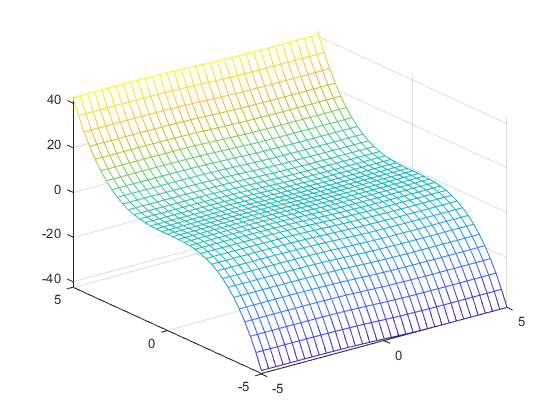

fmesh(eq1)

% 520
% Solve equation
% y'+cos(x+2*y)=cos(x-2*y)
% y(0)=pi/4

syms x y dy dx;
eq1=dy/dx+cos(x+2*y)-cos(x-2*y)

$$eq1 = \cos\left(x+2\,y\right)-\cos\left(x-2\,y\right)+\frac{\mathrm{dy}}{\mathrm{dx}}$$

eq1=simplify(eq1*dx)

$$eq1 = \mathrm{dy}-2\,\mathrm{dx}\,\sin\left(2\,y\right)\,\sin\left(x\right)$$

eq1=expand(eq1/sin(2*y))

$$eq1 = \frac{\mathrm{dy}}{2\,\cos\left(y\right)\,\sin\left(y\right)}-2\,\mathrm{dx}\,\sin\left(x\right)$$

cfs=simplify(coeffs(eq1,[dx dy]))

$$cfs = \left(\begin{array}{cc} \frac{1}{2\,\cos\left(y\right)\,\sin\left(y\right)} & -2\,\sin\left(x\right) \end{array}\right)$$

eq1=simplify(int(cfs(1),y)+int(cfs(2),x))+C

$$eq1 = C+\frac{\log\left(\tan\left(y\right)\right)}{2}+2\,\cos\left(x\right)$$

eq2=subs(eq1,[x y],[0 pi/4])

$$eq2 = C+2$$

eq1=simplify(subs(eq1,C,-2)*2)

$$eq1 = \log\left(\tan\left(y\right)\right)+4\,\cos\left(x\right)-4$$

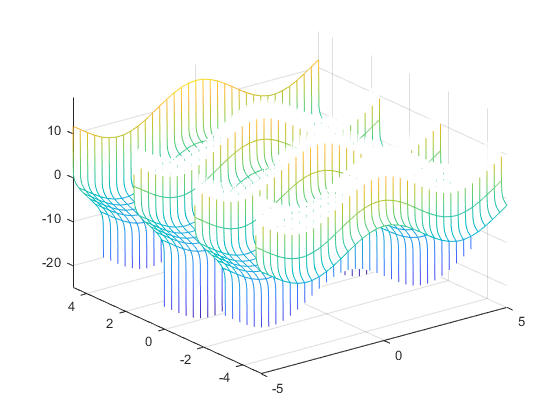

fmesh(eq1)

% #521
% Solve equation
% y'=2^(x-y)
% y(-3)=-5

clear
syms x y dx dy C real;
eq1=dy/dx-2^x/2^y

$$eq1 = \frac{\mathrm{dy}}{\mathrm{dx}}-\frac{2^{x}}{2^{y}}$$

eq1=expand(eq1*dx*2^y)

$$eq1 = 2^{y}\,\mathrm{dy}-2^{x}\,\mathrm{dx}$$

cfs=simplify(coeffs(eq1,[dx dy]))

$$cfs = \left(\begin{array}{cc} 2^{y} & -2^{x} \end{array}\right)$$

eq1=simplify(int(cfs(1),y)+int(cfs(2),x))+C

$$eq1 = C-\frac{2^{x}-2^{y}}{\log\left(2\right)}$$

C1=solve(subs(eq1,[x y],[-3 -5]),C)

$$C1 = \frac{3}{32\,\log\left(2\right)}$$

eq1=simplify(subs(eq1,C,C1)*log(sym(2)))

$$eq1 = 2^{y}-2^{x}+\frac{3}{32}$$

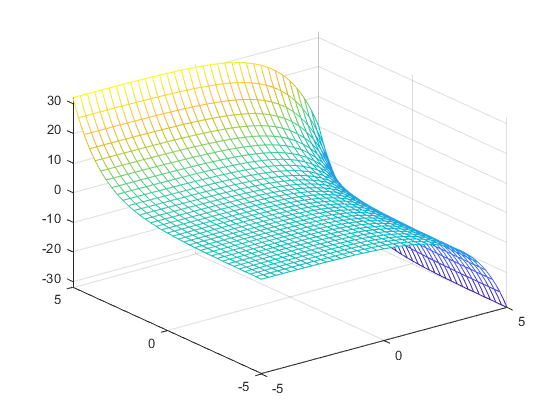

fmesh(eq1)

% #522
% Solve equation
% y*log(y)^3+y'*sqrt(x+1)=0
% y(-15/16)=e

clear
syms x y dx dy C e real;
eq1=y*log(y)^3+dy/dx*sqrt(x+1)

$$eq1 = y\,{\log\left(y\right)}^{3}+\frac{\mathrm{dy}\,\sqrt{x+1}}{\mathrm{dx}}$$

eq1=expand(eq1*dx/(y*log(y)^3)/sqrt(x+1))

$$eq1 = \frac{\mathrm{dx}}{\sqrt{x+1}}+\frac{\mathrm{dy}}{y\,{\log\left(y\right)}^{3}}$$

cfs=simplify(coeffs(eq1,[dx dy]))

$$cfs = \left(\begin{array}{cc} \frac{1}{y\,{\log\left(y\right)}^{3}} & \frac{1}{\sqrt{x+1}} \end{array}\right)$$

eq1=simplify(int(cfs(1),y)+int(cfs(2),x))+C

$$eq1 = C+2\,\sqrt{x+1}-\frac{1}{2\,{\log\left(y\right)}^{2}}$$

C1=solve(subs(eq1,[x y],[-15/16 e]),C)

$$C1 = \frac{1}{2\,{\log\left(e\right)}^{2}}-\frac{1}{2}$$

C1=0

C1 =      0


eq1=subs(eq1,C,C1)/2

$$eq1 = \sqrt{x+1}-\frac{1}{4\,{\log\left(y\right)}^{2}}$$

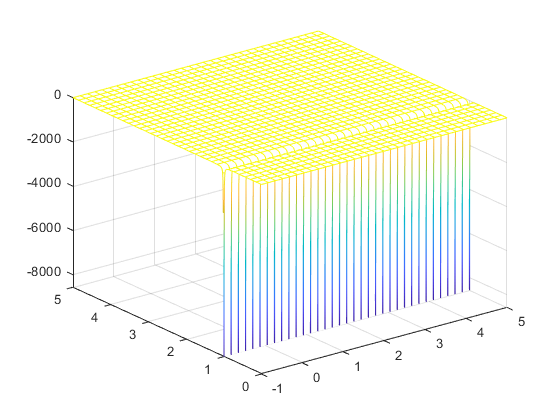

fmesh(eq1)